## Ann Fiegel - Class Project Part 5

Textbook problem 12.29

The distance a projectile travels when fired at an angle theta is a function of the time and can be divided into horizontal and vertical distances given respectively by 

horizontal = t.*V0*cos(theta)

vertical = t.*V0*sin(theta) - 0.5*g*t.^2

where

horizontal = distance traveled in the x direction

vertical = distance traveled in the y direction

V0 = initial velocity of the projectile

g = acceleration due to gravity (9.8 m/s^2)

t = time in seconds

Suppose a projectile is fired at an ainitial velocity of 100m/s, and a launch angle of pi/4 radians.

graph horizontal distance on the x axis and vertical distance on the y axis for times 0 to 20 seconds. 

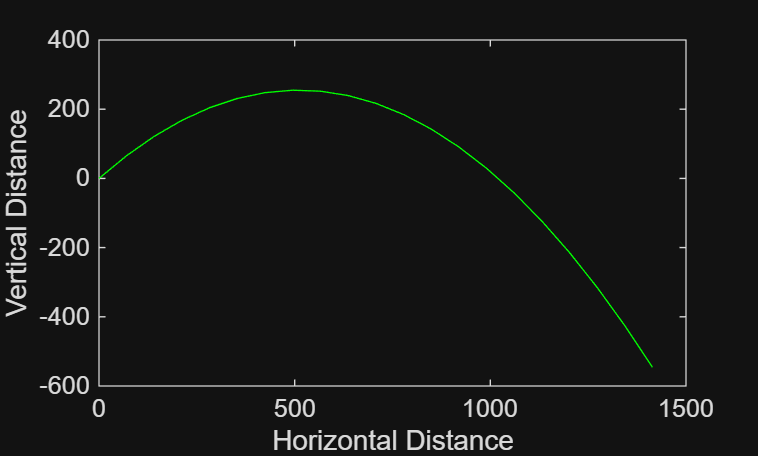


function horizontal = f(theta, V0, t) % creating a function that models the projectiles distance in the horizontal direction 
    horizontal = t.*V0*cos(theta); % plugging values into the equation and solving 
end % end of function 

function vertical = g(theta, V0, t) % creating a function that models the distance traveled by the projectile in the vertical direction 
    vertical = t.*V0*sin(theta) - 0.5*9.8*t.^2; % plugging values into the equation and solving 
end % end of function 

horizontal = f(pi/4, 100, 0:20); % calculating horizontal distances 

vertical = g(pi/4, 100, 0:20); % calculating vertical distances

plot(horizontal, vertical, 'g-'); % plotting the distances traveled as specified in the question
xlabel('Horizontal Distance'); % label for x axis
ylabel('Vertical Distance'); % label for y axis

The next section of code takes the model from the first part and makes it more versatile allowing other values for theta, V0, and t to be modeled. 

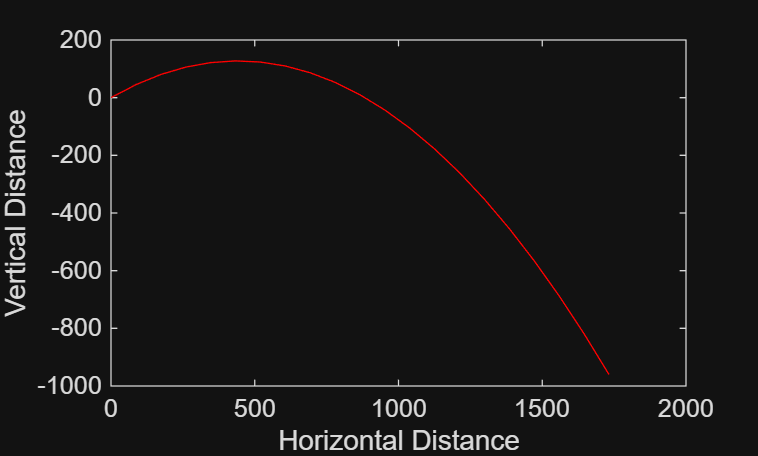

theta = input('Launch Angle:'); % setting launch angle to user input value
V0 = input('Initial Velocity:'); % setting initial velocity to user input value
t = input('Time of Travel, (start:end):'); % setting time to user input value

horizontal = f(theta, V0, t); % calculating horizontal distances 

vertical = g(theta, V0, t); % calculating vertical distances

plot(horizontal, vertical, 'r-'); % plotting the distances traveled on each axis
xlabel('Horizontal Distance'); % label for x axis
ylabel('Vertical Distance'); % label for y axis